# Introduction

## Who are we?

- Lecturer: LCL IMM Ben LAUWENS / D30.19 / [ben.lauwens@mil.be](mailto:ben.lauwens@mil.be)

- Assistant: 

## MATLAB: ES115

- Theory: 15 Hr

- Exercises: 16 Hr

- Workload: 77 Hr

## Documentation

Matlab Help

Notebooks available on github: [https://github.com/BenLauwens/ES115.](https://github.com/BenLauwens/ES121.)

## Schedule

Monday / Friday 2 + 1

## Evaluation

### Test

- 12/12: Written

- 2 Hr: Matrices, Numerical calculations, Plots

### Exam

- Written

- 4 Hr: Symbolic calculations, Numerical calculations, Plots, Programming

## Engineering and MATLAB

Engineers work in an environment that requires a strong technical background, and the computer will be the primary **computational tool** of most engineers. The focus of this text is to teach you the fundamentals of one of the most widely used engineering tools—MATLAB. However, engineers in the twenty-first century must also have many nontechnical skills and capabilities. The computer is also useful in developing additional nontechnical abilities.

Engineers are **problem solvers**, but problems are not always formulated carefully in the real world. An engineer must be able to extract a problem statement from a problem discussion and then determine the important issues. This involves not only developing order, but also learning to correlate chaos. It means not only analyzing the data, but also synthesizing a solution using many pieces of information. The integration of ideas can be as important as the decomposition of the problem into manageable pieces. A problem solution may involve not only abstract thinking about the problem, but also experimental learning from the problem environment.

## Engineering Computing and MATLAB

Before we begin discussing MATLAB, a brief discussion on computing is useful, especially for those who have not had lots of experience with computers. A computer is a machine that is designed to perform operations that are specified with a set of instructions called a program. Computer **hardware** refers to the computer equipment, such as a notebook computer, a thumb drive, a keyboard, a flat-screen monitor, or a printer. Computer **software** refers to the programs that describe the steps we want the computer to perform. This can be software that we have written, or it can be programs that we download or purchase, such as computer games. Our computer hardware/software can be self-contained, as in a notebook computer. A computer can also access both hardware and software through a computer network, and through access to the Internet. In fact, cloud computing provides access to hardware, software, and large data sets through remote networks.

### Computer Hardware

All computers have a common internal organization as shown below.

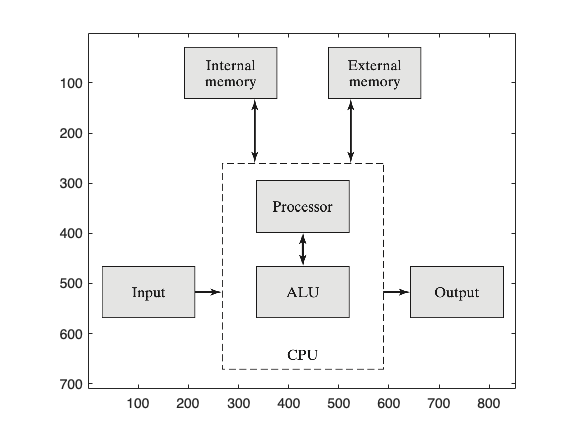

img = imread(['Hardware.png']);
image(img)
axis image

The **processor** is the part of the computer that controls all the other parts. It accepts input values (from a device such as a keyboard or a data file) and stores them in memory. It also interprets the instructions in a computer program. If we want to add two values, the processor will retrieve the values from memory and send them to the **arithmetic logic unit** (ALU). The ALU performs the addition, and the processor then stores the result in memory. The processing unit and the ALU use internal memory composed of read-only memory (ROM) and random access memory (RAM); data can also be stored in external storage devices such as external drives or thumb drives. The processor and the ALU together are called the **central processing unit** (CPU). A microprocessor is a CPU that is contained in a single integrated-circuitchip, which contains millions of components in an area much smaller than a postage stamp.

### Computer Software

Computer software contains the instructions or commands that we want the computer to perform. There are several important categories of software.

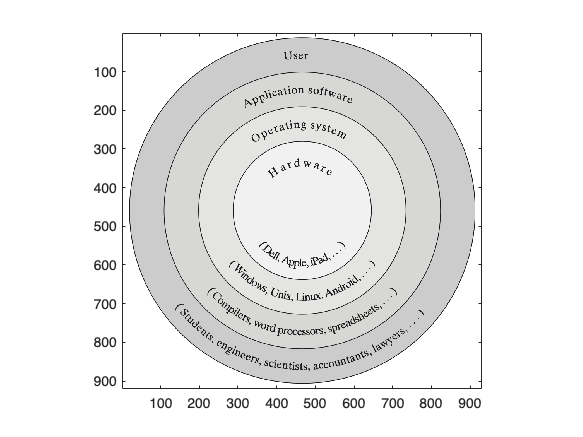

img = imread(['Software.png']);
image(img)
axis image

#### Operating Systems

Some software, such as an operating system, typically comes with the computer hardware when it is purchased. The operating system provides an interface between you (the user) and the hardware by providing a convenient and efficient environ ment in which you can select and execute the software application on your system. The component of the operating system that manages the interface between the hardware and software applications is called a kernel. Examples of desktop operating systems include Windows, Mac OS, Unix, and Linux. Operating systems for smartphones include Android (a Linux variant) and iOS (a Unix variant). Operating systems also contain a group of programs called utilities that allow you to perform functions such as printing files, copying files from one folder to another, and listing the files in a folder. Most operating systems today simplify using these utilities through icons and menus.

#### Software Tools

Software tools are programs that have been written to perform common operations. For example, word processors like Microsoft Word are programs that allow you to enter and format text. Spreadsheet programs like Excel are software tools that allow you to easily work with data that can be displayed in a grid of rows and columns. Spreadsheets were initially developed to be used for financial and accounting applications, but many science and engineering problems can be easily solved with spreadsheets. Most spreadsheet packages include plotting capabilities, so they are especially useful in analyzing and displaying information in charts.

Another important category of software tools is mathematical computation tools. This category includes MATLAB and Mathematica. Not only do these tools have very powerful mathematical commands, but they are also graphics tools that provide extensive capabilities for generating graphs. This combination of computational and visualization power make them particularly useful tools for engineers.

If an engineering problem can be solved using a software tool, it is usually more efficient to use the software tool than to write a program in a computer language. The distinction between a software tool and a computer language is becoming less clear as some of the more powerful software tools include their own language in addition to having specialized operations. (MATLAB is both a software tool and a programming language.)

#### Computer Languages

Computer languages can be described in terms of generations. The first generation of computer languages is **machine languages**. Machine languages are tied closely to the design of the computer hardware, and are often written in binary strings consisting of 0s and 1s. Therefore, machine language is also called binary language.

An **assembly language** is also unique to a specific computer design, but its instructions are written in symbolic statements instead of binary. Assembly languages usually do not have many statements; thus, writing programs in assembly language can be tedious. In addition, to use an assembly language you must also know information that relates to the specific hardware. Assembly languages are second generation languages.

Third generation languages use English-like commands. These languages include C, C++, C#, and Java. Writing programs in a **high-level language** is certainly easier than writing programs in machine language or in assembly language. However, a high-level language contains a large number of commands and an extensive set of syntax (or grammar) rules for using these commands.

MATLAB is considered a fourth generation programming language because of its powerful commands, user interfaces, and its ability to interface to other languages. 

### Executing a Computer Program

A program written in a high-level language such as C must be translated into machine language before the instructions can be executed by the computer. A special program called a compiler is used to perform this translation. Thus, in order to write and execute C programs, we must have a C compiler. The C compilers are available as separate software packages for use with specific operating systems.

If any errors (often called bugs) are detected by the compiler during compilation, corresponding error messages are printed. We must correct our program statements and then perform the compilation step again. The errors identified during this stage are called compiler errors or **compile-time errors**. For example, if we want to divide the value stored in a variable called sum by 3, the correct expression in C is sum/3; if we incorrectly write the expression using the backslash, as in sum\3, we will get a compiler error. The process of compiling, correcting statements (or ­ debugging), and recompiling is often repeated several times before the program compiles without compiler errors. When there are no compiler errors, the compiler generates a program in machine language that performs the steps specified by the original C program. The original C program is referred to as the source program, and the machine language version is called an object program. Thus, the source program and the object program specify the same steps; but the source program is written in a high-level language, and the object program is specified in machine language.

Once the program has compiled correctly, additional steps are necessary to prepare the object program for execution. This preparation involves linking other machine language statements to the object program and then loading the program into memory. After this linking/loading, the program steps are executed by the computer. New errors called execution errors, **run-time errors**, or **logic errors** may be identified in this stage; they are also called program bugs. Execution errors often cause the termination of a program. For example, the program statements may attempt to perform a division by zero, which generates an execution error. Some execution errors do not stop the program from executing, but they cause incorrect results to be computed. These types of errors can be caused by programmer errors in determining the correct steps in the solutions and by errors in the data processed by the program. When execution errors occur due to errors in the program statements, we must correct the errors in the source program and then begin again with the compilation step. Even when a program appears to execute properly, we must check the answers carefully to be sure that they are correct. The computer will perform the steps precisely as we specify, and if we specify the wrong steps, the computer will execute these wrong (but syntactically legal) steps and thus present us with an answer that is incorrect.

The process of compilation, linking/loading, and execution is outlined below. The process of converting an assembly language program to binary is performed by an assembler program, and the corresponding processes are called assembly, linking/loading, and execution.

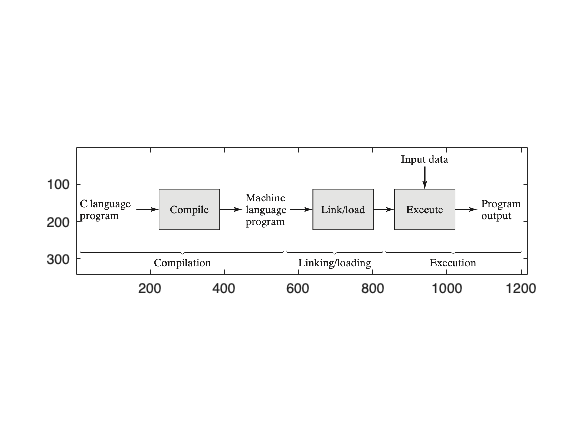

img = imread(['Execution.png']);
image(img)
axis image

### Software Life Cycle

The cost of a computer solution to a problem can be estimated in terms of the cost of the hardware and the cost of the software. The majority of the cost in a computer solution today is in the cost of the software, and thus, a great deal of attention has been given to understanding the development of a software solution.

The development of a software project generally follows definite steps or cycles, which are collectively called the software life cycle. These steps typically include project definition, detailed specification, coding and modular testing, integrated testing, and maintenance. The problem-solving process that we present in the next section emphasizes the need to define and specify the solution carefully before beginning to code or test it.

## An Engineering Problem-Solving Methodology

Problem solving is a key part not only of engineering courses, but also of courses in computer science, mathematics, physics, and chemistry. Therefore, it is important to have a consistent approach to solving problems. It is also helpful if the approach is general enough to work for all these different areas, so that we do not have to learn one technique for solving mathematics problems, a different technique for solving physics problems, and so on. The problem-solving process that we present works for engineering problems and can be tailored to solve problems in other areas as well. However, it does assume that we are using a computer to help solve the problem.

The process, or methodology, for problem solving that we will use throughout this text has five steps:

- State the problem clearly.

- Describe the input and output information.

- Work the problem by hand (or with a calculator) for a simple set of data.

- Develop a MATLAB solution.

- Test the solution with a variety of data.

### Example: Temperature analysis and plot

Assume that we have collected a set of temperatures from a sensor on a piece of equipment that is being used in an experiment. The temperature measurements shown in the table are taken every 30 seconds, for 5 minutes, during the experiment. We want to compute the average temperature, and we also want to plot the temperature values.

#### Problem Statement

The first step is to state the problem clearly. It is extremely important to give a clear, concise statement of the problem, in order to avoid any misunderstandings. For this example, the statement of the problem is as follows:

Compute the average of a set of temperatures. Then plot the time and temperature values.

#### Input/Output Description

The second step is to describe carefully the information that is given to solve the problem and then to identify the values to be computed. These items represent the input and the output for the problem and collectively can be called input/output, or I/O. For many problems, it is useful to create a diagram that shows the input and output. At this point, the program is called an abstraction because we are not defining the steps to determine the output; instead, we are only showing the information that is used to compute the output. The I/O diagram for this example is as follows:

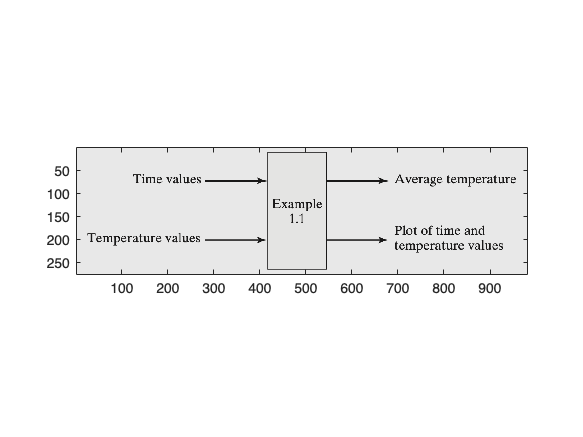

img = imread(['Diagram.png']);
image(img)
axis image

#### Hand Example

The third step is to work the problem by hand or with a calculator, using a simple set of data. This step is very important and should not be skipped, even for simple problems. This is the step in which you work out the details of the solution to the problem. If you cannot take a simple set of numbers and compute the output (either by hand or with a calculator), you are not ready to move on to the next step. You should reread the problem and perhaps consult reference material. For this problem, the only calculation is computing the average, or mean value, of a set of temperature values. Assume that we use the first three sets of data for the hand example. By hand, we compute the average to be (40+52+48)/3, or 46.6667.

#### Matlab Solution

Once you can work the problem for a simple set of data, you are ready to develop an **algorithm**, which is a step-by-step outline of the solution to the problem. For simple problems such as this one, the algorithm can be written immediately using MATLAB commands. For more complicated problems, it may be necessary to write an outline of the steps and then decompose the steps into smaller steps that can be translated into MATLAB commands. One of the strengths of MATLAB is that its commands match very closely to the steps that we use to solve engineering problems. Thus, the process of determining the steps to solve the problem also determines the MATLAB commands. At this point, we know that you do not yet understand the MATLAB commands. However, we present the solution so you can observe that the MATLAB steps match closely to the solution steps from the hand example:

time = [0.0,0.5,1.0];
temps = [40, 52, 48];
average = mean(temps)

average = 46.6667

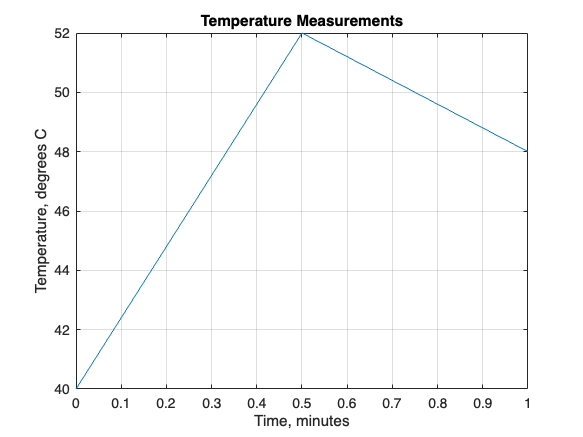

plot(time,temps),title('Temperature Measurements'),
xlabel('Time, minutes'),
ylabel('Temperature, degrees C'),grid

If a MATLAB statement assigns or computes a value, it will also print the value on the screen if the statement does not end in a semicolon. Thus, the values of `time` and `temps` will not be printed, because the statements that assign them values end with semicolons. The value of the average will be computed and printed on the screen, because the statement that computes it does not end with a semicolon. Finally, a plot of the time and temperature data will be generated.

#### Testing

The final step in our problem-solving process is testing the solution. We should first test the solution with the data from the hand example, because we have already computed the solution to it. When the previous statements are executed, the computer displays the following output:

average

average = 46.6667

A plot of the data points is also shown on the screen. Because the value of the aver-

age computed by the program matches the value from the hand example, we now

replace the data from the hand example with the data from the physics experiment

using these replacement statements:

time = [0.0,0.5,1.0,1.5,2.0,2.5,3.0,3.5,4.0,4.5,5.0];
temps = [40, 52, 48, 54, 56,53, 55, 57, 58, 56, 58];
average = mean(temps)

average = 53.3636

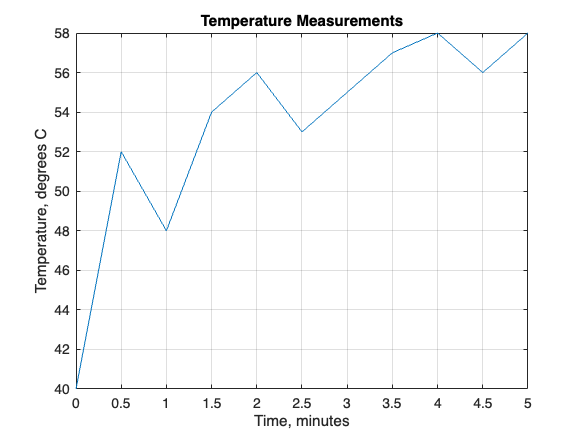

plot(time,temps),title('Temperature Measurements'),
xlabel('Time, minutes'),
ylabel('Temperature, degrees C'),grid